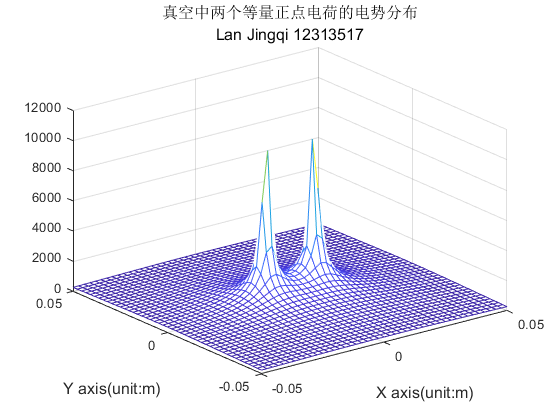

%%case 1: 两个等量正点电荷的电场分布
k = 9e9;
Q1 = 1e-9;
Q2 = 1e-9;
xm = 0.05;
ym = 0.05;
x = linspace(-xm,xm,45);
y = linspace(-ym,ym,45);
[X,Y] = meshgrid(x,y);
R1 = sqrt((X+0.01).^2+Y.^2);
R2 = sqrt((X-0.01).^2+Y.^2);
V1 = k*Q1./R1;
V2 = k*Q2./R2;
V = V1+V2;
mesh(X,Y,V)
hold on;
title({'真空中两个等量正点电荷的电势分布', 'Lan Jingqi 12313517'}, 'fontsize',12); 
xlabel('X axis(unit:m)','FontSize',12);
ylabel('Y axis(unit:m)','FontSize',12);
hold off;

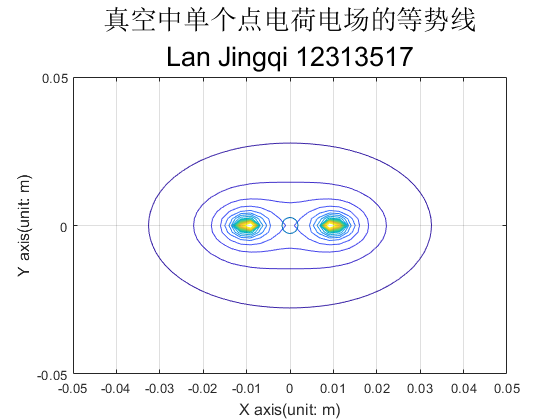


Vmin = 200;
Vmax = 8000;
Veq = linspace(Vmin,Vmax,20);
contour(X,Y,V,Veq);
grid on;
hold on;
plot(0,0,'o', 'MarkerSize',12)                            
title({'真空中单个点电荷电场的等势线', 'Lan Jingqi 12313517'}, 'fontsize', 20);
xlabel('X axis(unit: m)', 'fontsize', 12);       
ylabel('Y axis(unit: m)', 'fontsize', 12); 
hold off;

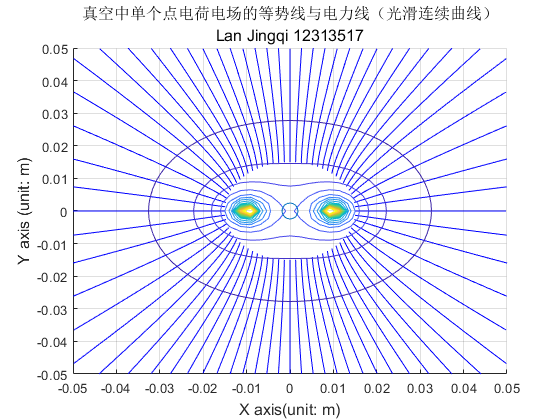


[Ex,Ey]=gradient(-V);                                 
del_theta=5;                                      
theta=(0:del_theta:360).*pi/180;                       
xs=0.015*cos(theta);                                 
ys=0.015*sin(theta);
figure;
streamline(X,Y,Ex,Ey,xs,ys)                            
grid on                                           
hold on                                            
contour(X,Y,V,Veq);                                   
plot(0,0,'o', 'MarkerSize',12)                           
title({'真空中单个点电荷电场的等势线与电力线（光滑连续曲线）', 'Lan Jingqi 12313517'}, 'fontsize',12);              % title the plot
xlabel('X axis(unit: m)', 'fontsize', 12);                   
ylabel('Y axis (unit: m)', 'fontsize', 12);                    
hold off;

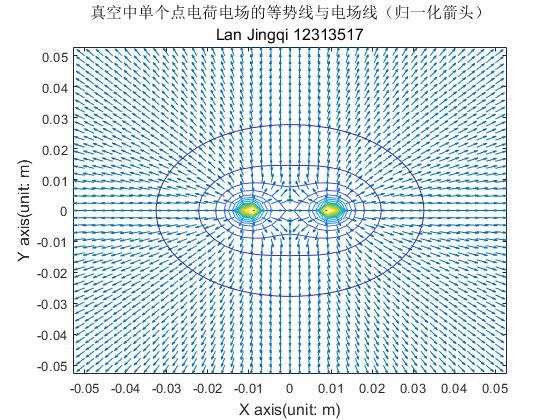


E=sqrt(Ex.^2+Ey.^2);                        
Ex=Ex./E;                                
Ey=Ey./E;                                 
quiver(X,Y,Ex,Ey);                           
hold on;
contour(X,Y,V,Veq);                         
title({'真空中单个点电荷电场的等势线与电场线（归一化箭头）', 'Lan Jingqi 12313517'}, 'fontsize', 12);                                       
xlabel('X axis(unit: m)', 'fontsize', 12);           
ylabel('Y axis(unit: m)', 'fontsize', 12);
hold off;

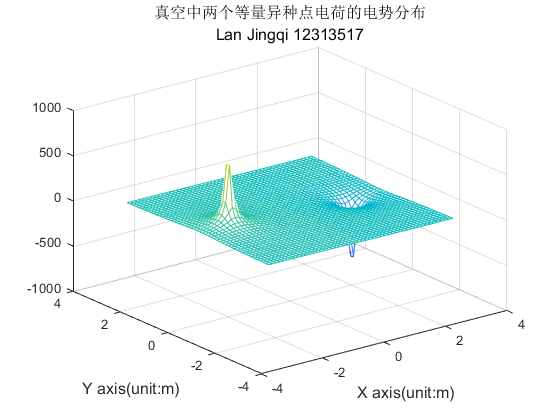


%%case 2: 两个等量异种点电荷的电场分布
k = 9e9;
Q1 = 5e-9;
Q2 = -5e-9;
xm = 3;
ym = 3;
P1 = [-2,0];
P2 = [2,0];
x = linspace(-xm,xm,50);
y = linspace(-ym,ym,50);
[X,Y] = meshgrid(x,y);
R1 = sqrt((X+2).^2+Y.^2);
R2 = sqrt((X-2).^2+Y.^2);
V1 = k*Q1./R1;
V2 = k*Q2./R2;
V = V1+V2;
mesh(X,Y,V)
hold on;
title({'真空中两个等量异种点电荷的电势分布', 'Lan Jingqi 12313517'}, 'fontsize',12); 
xlabel('X axis(unit:m)','FontSize',12);
ylabel('Y axis(unit:m)','FontSize',12);
hold off;

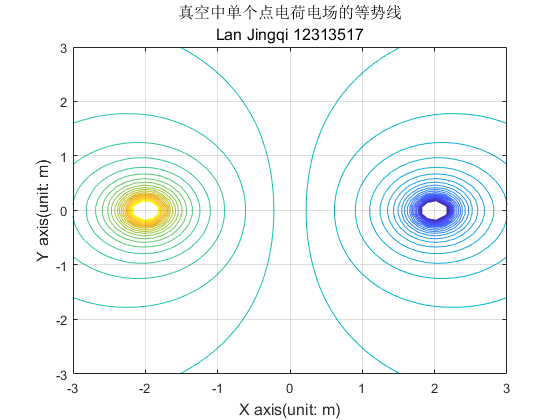


Vmin = -250;
Vmax = 250;
Veq = linspace(Vmin,Vmax,50);
contour(X,Y,V,Veq);
grid on;
hold on;                            
title({'真空中单个点电荷电场的等势线', 'Lan Jingqi 12313517'}, 'fontsize', 12);
xlabel('X axis(unit: m)', 'fontsize', 12);       
ylabel('Y axis(unit: m)', 'fontsize', 12); 
hold off;

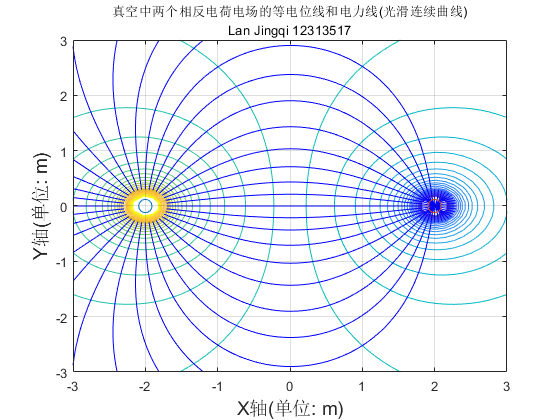


[Ex,Ey]=gradient(-V);                           
del_theta=10;
theta=(0:del_theta:360).*pi/180; 
startx_pos = P1(1) + 0.3*cos(theta); % 正电荷周围起始点
starty_pos = P1(2) + 0.3*sin(theta);
startx_neg = P2(1) + 0.3*cos(theta); % 负电荷周围起始点
starty_neg = P2(2) + 0.3*sin(theta);

figure
contour(X,Y,V,Veq);
grid on,hold on;
h = streamline(X, Y, Ex, Ey, [startx_pos startx_neg], [starty_pos starty_neg]);
hold on;
plot(-2,0,'o', 'MarkerSize',10);
hold on;
plot(2,0,'o', 'MarkerSize',10);
hold off;

title({'真空中两个相反电荷电场的等电位线和电力线(光滑连续曲线)', 'Lan Jingqi 12313517'}, 'fontsize', 10);
xlabel('X轴(单位: m)', 'fontsize', 14);
ylabel('Y轴(单位: m)', 'fontsize', 14);

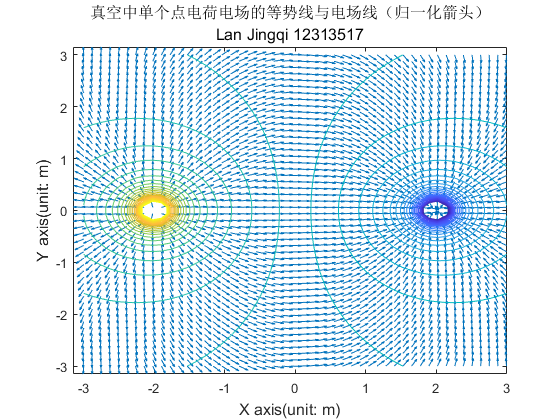


E=sqrt(Ex.^2+Ey.^2);                        
Ex=Ex./E;                                
Ey=Ey./E;                                 
quiver(X,Y,Ex,Ey);                           
hold on;
contour(X,Y,V,Veq);                         
title({'真空中单个点电荷电场的等势线与电场线（归一化箭头）', 'Lan Jingqi 12313517'}, 'fontsize', 12);                                       
xlabel('X axis(unit: m)', 'fontsize', 12);           
ylabel('Y axis(unit: m)', 'fontsize', 12);
hold off;

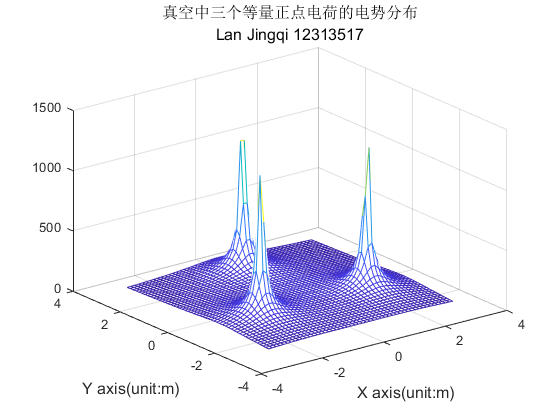


%%case 3: 三个等量正点电荷的电场分布（等边三角形布置）
k = 9e9;
Q1 = 8e-9;
Q2 = 8e-9;
Q3 = 8e-9;
xm = 3;
ym = 3;
x = linspace(-xm,xm,50);
y = linspace(-ym,ym,50);
[X,Y] = meshgrid(x,y);
R1 = sqrt((X+sqrt(3)).^2+(Y+1).^2);
R2 = sqrt((X-sqrt(3)).^2+(Y+1).^2);
R3 = sqrt(X.^2+(Y-2).^2);
P1 = [-sqrt(3),-1]; P2 = [sqrt(3),-1]; P3 = [0,2];
V1 = k*Q1./R1;
V2 = k*Q2./R2;
V3 = k*Q3./R3;
V = V1+V2+V3;
mesh(X,Y,V)
hold on;
title({'真空中三个等量正点电荷的电势分布', 'Lan Jingqi 12313517'}, 'fontsize',12); 
xlabel('X axis(unit:m)','FontSize',12);
ylabel('Y axis(unit:m)','FontSize',12);
hold off;

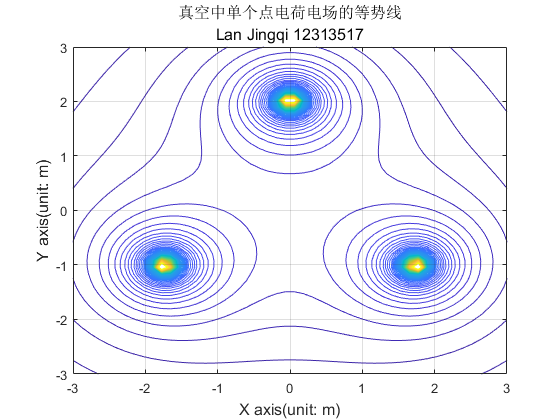


Vmin = -1000;
Vmax = 1000;
Veq = linspace(Vmin,Vmax,150);
contour(X,Y,V,Veq);
grid on;
hold on;                        
title({'真空中单个点电荷电场的等势线', 'Lan Jingqi 12313517'}, 'fontsize', 12);
xlabel('X axis(unit: m)', 'fontsize', 12);       
ylabel('Y axis(unit: m)', 'fontsize', 12); 
hold off;

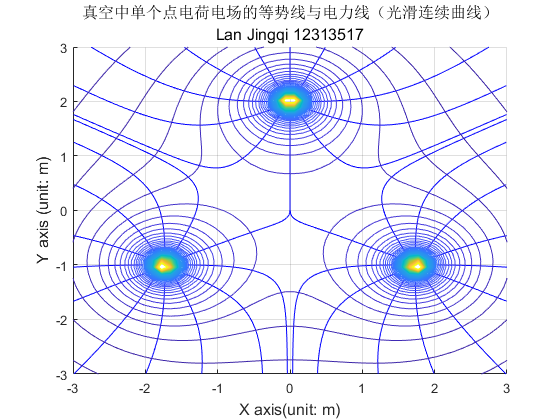


[Ex,Ey]=gradient(-V);                                 
del_theta=5;                                      
theta=(0:del_theta:360).*pi/180;                       
xs = [P1(1)+0.3*cos(0:pi/6:2*pi), P2(1)+0.3*cos(0:pi/6:2*pi), P3(1)+0.3*cos(0:pi/6:2*pi)];
ys = [P1(2)+0.3*sin(0:pi/6:2*pi), P2(2)+0.3*sin(0:pi/6:2*pi), P3(2)+0.3*sin(0:pi/6:2*pi)];
figure;
streamline(X,Y,Ex,Ey,xs,ys)                            
grid on                                           
hold on                                            
contour(X,Y,V,Veq);                                                           
title({'真空中单个点电荷电场的等势线与电力线（光滑连续曲线）', 'Lan Jingqi 12313517'}, 'fontsize',12);              % title the plot
xlabel('X axis(unit: m)', 'fontsize', 12);                   
ylabel('Y axis (unit: m)', 'fontsize', 12);                    
hold off;

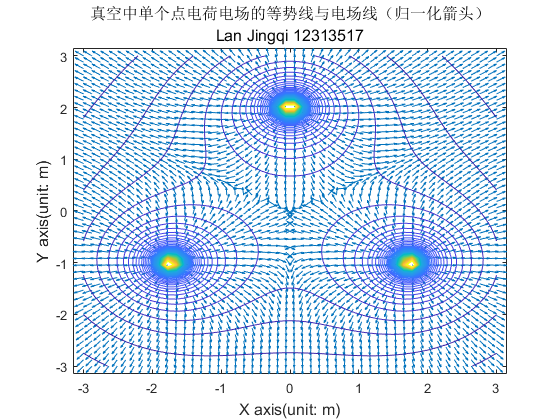


E=sqrt(Ex.^2+Ey.^2);                        
Ex=Ex./E;                                
Ey=Ey./E;                                 
quiver(X,Y,Ex,Ey);                           
hold on;
contour(X,Y,V,Veq);                         
title({'真空中单个点电荷电场的等势线与电场线（归一化箭头）', 'Lan Jingqi 12313517'}, 'fontsize', 12);                                       
xlabel('X axis(unit: m)', 'fontsize', 12);           
ylabel('Y axis(unit: m)', 'fontsize', 12);
hold off;